# `Experiment-3`

### 1) RK-Method:

(1) Solve the IVP $\frac{\textrm{dy}}{\textrm{dx}}=x^2 y$ ,$y\left(0\right)=1$, in the range of $0<x<2$ and take  $h=0\ldotp 1$.

% Inputs (Change according to given problems)
x0=0;
y0=1;
h=0.1;
xn=2;
f=@(x,y)x^2*y; % slope
x=x0:h:xn; % x range
n=length(x)-1; % length of x
y(1)=y0; %Intialization
for i=1:n
    k1=h*f(x(i),y(i));
    k2=h*f(x(i)+0.5*h,y(i)+0.5*k1);
    k3=h*f(x(i)+0.5*h,y(i)+0.5*k2);
    k4=h*f(x(i)+h,y(i)+k3);
    y(i+1)=y(i)+(1/6)*(k1+2*k2+2*k3+k4);
end
% Solution at x=0.1 and x=0.2
y01=y(2)

y01 = 1.0003

y02=y(3)

y02 = 1.0027

fprintf('Approximate solution at x=%f is y=%f\n',xn,y(end))

Approximate solution at x=2.000000 is y=14.390176


% Exact solution
syms u(t)
de=diff(u,t)==t^2*u;
ic=u(0)==1;
z=dsolve(de,ic)

$$z = {\mathrm{e}}^{\frac{t^{3}}{3}}$$

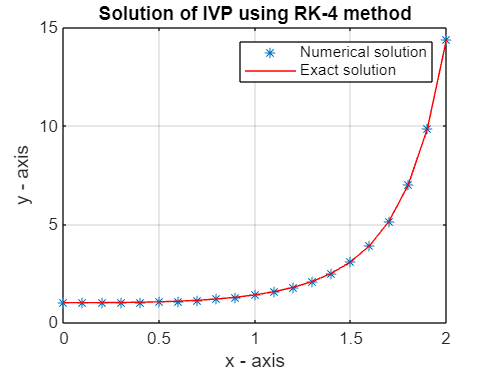

t=x0:h:xn;
z=eval(z);
plot(x,y,'*',t,z,'r')
grid on
xlabel('x - axis')
ylabel('y - axis')
title('Solution of IVP using RK-4 method')
legend('Numerical solution','Exact solution')

(2) Solve $\frac{\textrm{dy}}{\textrm{dx}}=x^2 +y^2$,$y\left(0\right)=1$ in the range of $\left\lbrack 0,0\ldotp 5\right\rbrack$ with $h=0\ldotp 1$, also find the value of $y\left(0\ldotp 2\right)$.

clearvars
% Initial Condititon
x0=0;
y0=1;
h=0.1;
xn=0.5;
f=@(x,y) x.^2+y.^2;

%Range
x=x0:h:xn;
n=length(x)-1;
y(1)=y0;

for i=1:n
    k1=h*f(x(i),y(i));
    k2=h*f(x(i)+0.5*h,y(i)+0.5*k1);
    k3=h*f(x(i)+0.5*h,y(i)+0.5*k2);
    k4=h*f(x(i)+h,y(i)+k3);
    y(i+1)=y(i)+(1/6)*(k1+2*k2+2*k3+k4);
end

%Displaying solution
y(1:end)

ans =     1.0000    1.1115    1.2530    1.4397    1.6961    2.0670


disp('The value of y at x=0.2 is');

The value of y at x=0.2 is


disp(y(3))

    1.2530



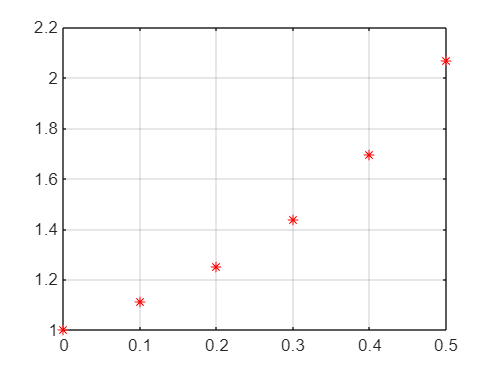


%Plotting of the values
plot(x,y,'r*')
grid on

**(No need in Record)**

Q. Solve $\frac{d^2 y}{dx^2 }-x^2 \frac{\textrm{dy}}{\textrm{dx}}-2\textrm{xy}=1\;,y\left(0\right)=1,y^{\prime } \left(0\right)=0$ with the range $\left\lbrack 0,1\right\rbrack$with $h=0\ldotp 1$and also find$y\left(0\ldotp 1\right)$.

% Define the differential equation: d^2y/dx^2 - x^2*dy/dx - 2*x*y = 1
% Rewrite it as a system of first-order equations:
% Let u = dy/dx, then du/dx = x^2*u + 2*x*y - 1

% Initial conditions
x0 = 0;
y0 = 1;
u0 = 0;

% Step size
h = 0.1;

% Number of steps
n = 10;

% Initialization
x = zeros(n+1, 1);
y = zeros(n+1, 1);
u = zeros(n+1, 1);

% Set initial values
x(1) = x0;
y(1) = y0;
u(1) = u0;

% Euler's method
for i = 1:n
    x(i+1) = x(i) + h;
    u(i+1) = u(i) + h * (x(i)^2 * u(i) + 2 * x(i) * y(i) - 1);
    y(i+1) = y(i) + h * u(i);
end

% Display the result
fprintf('Approximate value of y(0.1): %.4f\n', y(end));

Approximate value of y(0.1): 0.7562


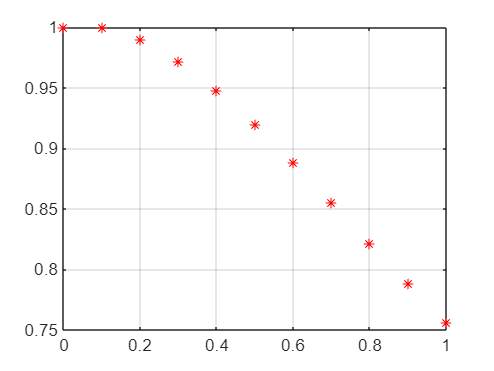


% Plot the solution
plot(x, y, 'r*')
grid on

### 2) Milne's P-C Method

(1) Write the matlab code to solve $\frac{\textrm{dy}}{\textrm{dx}}=x^2 -y^2$, $y\left(0\right)=1$ at $y\left(0\right)=1$at $x=0\ldotp 4$,with the step size $h=0\ldotp 1$.

%inputs
clearvars
x0=0;
y0=1;
h=0.1;
xn=1;
f=@(x,y) x^2-y^2; %slope
x=x0:h:xn; %x range
n=length(x)-1; %length of x
y(1)=y0; %initialization

for i=1:n
k1=h*f(x(i),y(i));
k2=h*f(x(i)+0.5*h,y(i)+0.5*k1);
k3=h*f(x(i)+0.5*h,y(i)+0.5*k2);
k4=h*f(x(i)+h,y(i)+k3);
y(i+1)=y(i)+(1/6)*(k1+2*k2+2*k3+k4)
end

y =     1.0000    0.9094


y =     1.0000    0.9094    0.8358


y =     1.0000    0.9094    0.8358    0.7772


y =     1.0000    0.9094    0.8358    0.7772    0.7327


y =     1.0000    0.9094    0.8358    0.7772    0.7327    0.7018


y =     1.0000    0.9094    0.8358    0.7772    0.7327    0.7018    0.6842


y =     1.0000    0.9094    0.8358    0.7772    0.7327    0.7018    0.6842    0.6802


y =     1.0000    0.9094    0.8358    0.7772    0.7327    0.7018    0.6842    0.6802    0.6897


y =     1.0000    0.9094    0.8358    0.7772    0.7327    0.7018    0.6842    0.6802    0.6897    0.7130


y =     1.0000    0.9094    0.8358    0.7772    0.7327    0.7018    0.6842    0.6802    0.6897    0.7130    0.7500



%milne's predictor and corrector method
for i=4:n
y(i+1)=y(i-3)+(4*h/3)*(2*f(x(i-2),y(i-2))-f(x(i-1),y(i-1))+2*f(x(i),y(i)));
y(i+1)=y(i-1)+(h/3)*(f(x(i-1),y(i-1))+4*f(x(i),y(i))+f(x(i+1),y(i+1)));
end
disp(y(5))

    0.7327



disp(y(end))

    0.7500



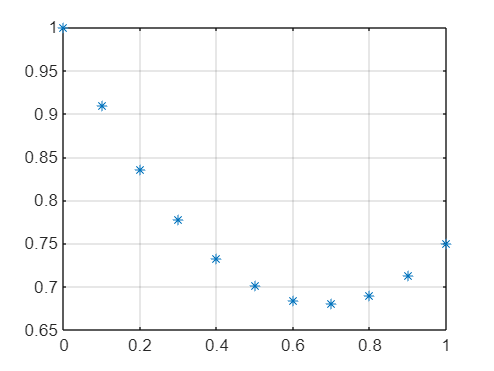

plot(x,y,'*')
grid on

(2) Write the matlab code to solve $\frac{\textrm{dy}}{\textrm{dx}}=x-y$, $y\left(0\right)=1$ at $y\left(0\right)=1$at $x=0\ldotp 4$,with the step size $h=0\ldotp 1$.

%inputs
clearvars
x0=0;
y0=1;
h=0.1;
xn=1;
f=@(x,y) x-y; %slope
x=x0:h:xn; %x range
n=length(x)-1; %length of x
y(1)=y0; %initialization

for i=1:n
k1=h*f(x(i),y(i));
k2=h*f(x(i)+0.5*h,y(i)+0.5*k1);
k3=h*f(x(i)+0.5*h,y(i)+0.5*k2);
k4=h*f(x(i)+h,y(i)+k3);
y(i+1)=y(i)+(1/6)*(k1+2*k2+2*k3+k4)
end

y =     1.0000    0.9097


y =     1.0000    0.9097    0.8375


y =     1.0000    0.9097    0.8375    0.7816


y =     1.0000    0.9097    0.8375    0.7816    0.7406


y =     1.0000    0.9097    0.8375    0.7816    0.7406    0.7131


y =     1.0000    0.9097    0.8375    0.7816    0.7406    0.7131    0.6976


y =     1.0000    0.9097    0.8375    0.7816    0.7406    0.7131    0.6976    0.6932


y =     1.0000    0.9097    0.8375    0.7816    0.7406    0.7131    0.6976    0.6932    0.6987


y =     1.0000    0.9097    0.8375    0.7816    0.7406    0.7131    0.6976    0.6932    0.6987    0.7131


y =     1.0000    0.9097    0.8375    0.7816    0.7406    0.7131    0.6976    0.6932    0.6987    0.7131    0.7358



%milne's predictor and corrector method
for i=4:n
y(i+1)=y(i-3)+(4*h/3)*(2*f(x(i-2),y(i-2))-f(x(i-1),y(i-1))+2*f(x(i),y(i)));
y(i+1)=y(i-1)+(h/3)*(f(x(i-1),y(i-1))+4*f(x(i),y(i))+f(x(i+1),y(i+1)));
end
disp(y(5))

    0.7406



disp(y(end))

    0.7358



z=dsolve('Dy=x-y','y(0)=1','x')

$$z = x+2\,{\mathrm{e}}^{-x}-1$$

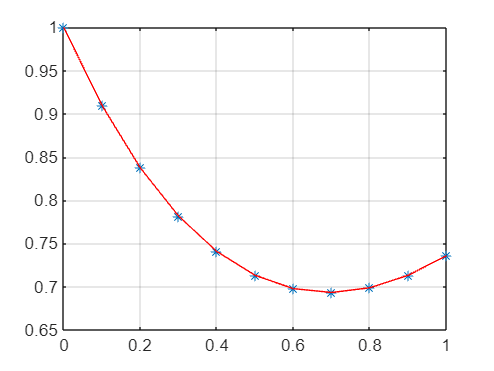

u=eval(z);
plot(x,y,'*',x,u,'r')
grid on